# Capillary Transition Zone Simulation

clc
clear
close all

## Setting up model

### Reservoir Geometry

Cell dimensions: $20\times 20\times 20$

Physical dimensions: $100\times 100\times 100\;m^3$

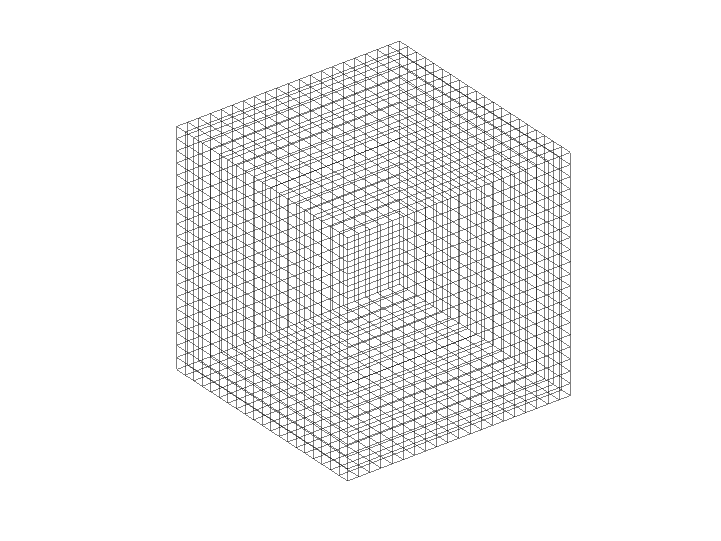

[Nx,Ny,Nz] = deal(20,20,20);
[Lx,Ly,Lz] = deal(100,100,100);
G = cartGrid([Nx,Ny,Nz],[Lx,Ly,Lz]);
plotGrid(G,'FaceColor','none','EdgeAlpha',0.5)
axis equal
axis tight off
view(3)

G = computeGeometry(G);

### Rock properties

Heterogeneous isotropic reservoir:                  


$$\phi =0\ldotp 20$$


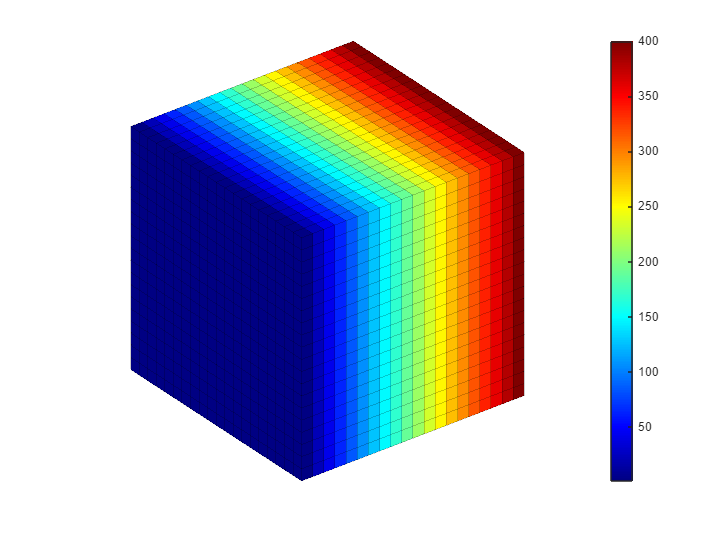

K = linspace(1,400,Nx);
K = repmat(K,1,Ny,Nz);
rock = makeRock(G,K(:)*milli*darcy,0.2);
plotCellData(G,rock.perm/(milli*darcy),'EdgeAlpha',0.2)
colormap(jet)
colorbar
caxis([1 400])

hT = computeTrans(G,rock);

### **Fluid properties**

### 
$$\mu_w =1\;\textrm{cP}\;\;\;\;\;\;\;\;\;\;\;\mu_o =5\;\textrm{cP}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\rho_w =1000\;\textrm{kg}/m^3 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\rho_o =700\;\textrm{kg}/m^3$$


### **Simplifed Brooks & Corey (Corey) model with exponent 2 and zero residual saturations:**

### 
$$K_{\mathrm{rw}} ={S_w }^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;K_{\mathrm{ro}} ={\left(1-S_w \right)}^2$$


### **Simplified Leverett J-function:**

### 
$$P_c \left(S_w \right)=\sigma \sqrt{\frac{\phi }{K}}\left(1-S_w \right)$$


gravity reset on
mrstModule add incomp

No module mapping found for
  * incomp


fluid = initSimpleFluidJfunc('mu',[1,5]*centi*poise,'rho',[1000,700],'n',[2 2],'surf_tension',50*dyne/(centi*meter),'rock',rock);

### Setting initial conditions

state = initResSol(G, 100*barsa,0);
state.s(G.cells.centroids(:,3) > Lz/2) = 1;

Total simulation time = 5 years

dt = 0.01*[1 1 2 2 3 3 4 4 repmat(5,[1,96])]*year;
dt = [dt(1)*sort(repmat(2.^-[1:5 5],1,1)),dt(2:end)];

### Plotting results

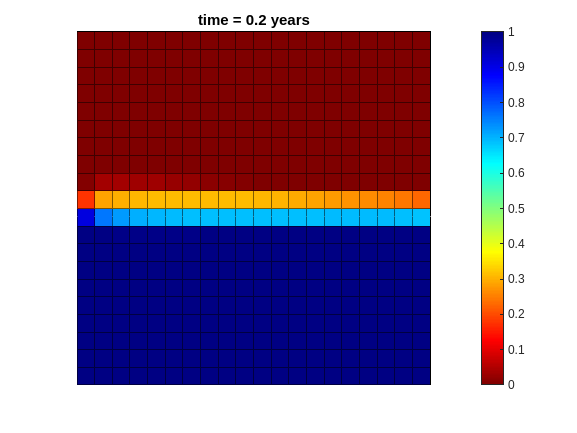

s  = state.s(:,1);
t = 0;
cla
colormap(flipud(jet))
colorbar
for k = 1 : numel(dt)
   state = incompTPFA(state, G, hT, fluid);
   state = implicitTransport(state, G, dt(k), rock, fluid);
   t  = t + dt(k);
     
   % Plot solution
   plotCellData(G,state.s(:,1),'EdgeColor','k','EdgeAlpha',0.5)
   view(0,0)
   caxis([0 1]);
   title(sprintf('time = %.1f years', t/year))
   drawnow

   ds = norm(s - state.s(:,1),inf);
   if ds < 1e-4
       break
   end
   s = state.s(:,1);

end

view(3)